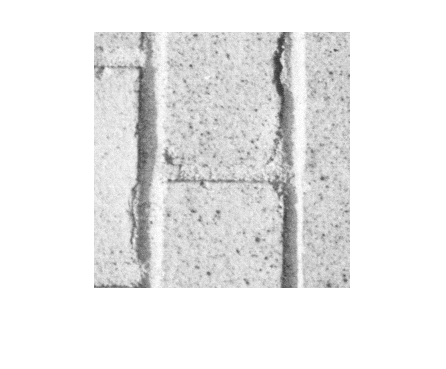

A = double(imread("media/texture_brick.tiff"));
A = A(1:256, 1:256);
imshow(A/255);

sigma = double(zeros(256,256));
sigma(randperm(numel(sigma), 45875)) = 1.0;
A1 = A.*sigma;
I_final_n = zeros(256,256);
I_final = double(zeros(256,256));
for i=4:253
    for j=4:253
        patch = A1(i-3:i+3,j-3:j+3);
        window = A1(max(1,i-10):min(256,i+10),max(1,j-10):min(256,j+10));
        sigm_wind = sigma(max(1,i-10):min(256,i+10),max(1,j-10):min(256,j+10));
        x_1 = i-3-max(1,i-10)+1;
        y_1 = j-3-max(1,j-10)+1;
        recover = SVT(window, sigm_wind, 10, min(256,i+10)-max(1,i-10)+1,min(256,j+10)-max(1,j-10)+1);
        rec_patch = recover(x_1:x_1+6,y_1:y_1+6);
        I_final(i-3:i+3,j-3:j+3) = I_final(i-3:i+3,j-3:j+3) + rec_patch;
        I_final_n(i-3:i+3,j-3:j+3) = I_final_n(i-3:i+3,j-3:j+3) +1;
    end
end
I_final = I_final./I_final_n;
rmse = norm(I_final-A,'fro')/norm(A,'fro')

rmse = 0.5415

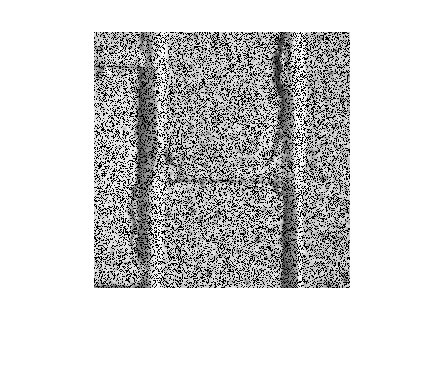

imshow(I_final/255);

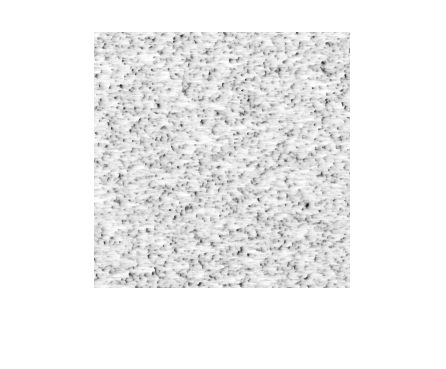

A = double(imread("media/textture_sand.tiff"));
A = A(1:256, 1:256);
imshow(A/255);

sigma = (zeros(256,256));
sigma(randperm(numel(sigma), 45875)) = 1;
A1 = A.*sigma;
I_final_n = zeros(256,256);
I_final = double(zeros(256,256));
for i=4:253
    for j=4:253
        patch = A1(i-3:i+3,j-3:j+3);
        window = A1(max(1,i-10):min(256,i+10),max(1,j-10):min(256,j+10));
        sigm_wind = sigma(max(1,i-10):min(256,i+10),max(1,j-10):min(256,j+10));
        x_1 = i-3-max(1,i-10)+1;
        y_1 = j-3-max(1,j-10)+1;
        recover = SVT(window, sigm_wind, 0.01, min(256,i+10)-max(1,i-10)+1,min(256,j+10)-max(1,j-10)+1);
        rec_patch = recover(x_1:x_1+6,y_1:y_1+6);
        I_final(i-3:i+3,j-3:j+3) = I_final(i-3:i+3,j-3:j+3) + rec_patch;
        I_final_n(i-3:i+3,j-3:j+3) = I_final_n(i-3:i+3,j-3:j+3) +1;
    end
end
I_final = I_final./I_final_n;
rmse = norm(I_final-A,'fro')/norm(A,'fro')

rmse = 0.5472

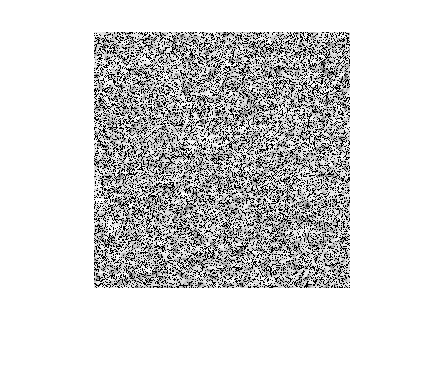

imshow(I_final/255);